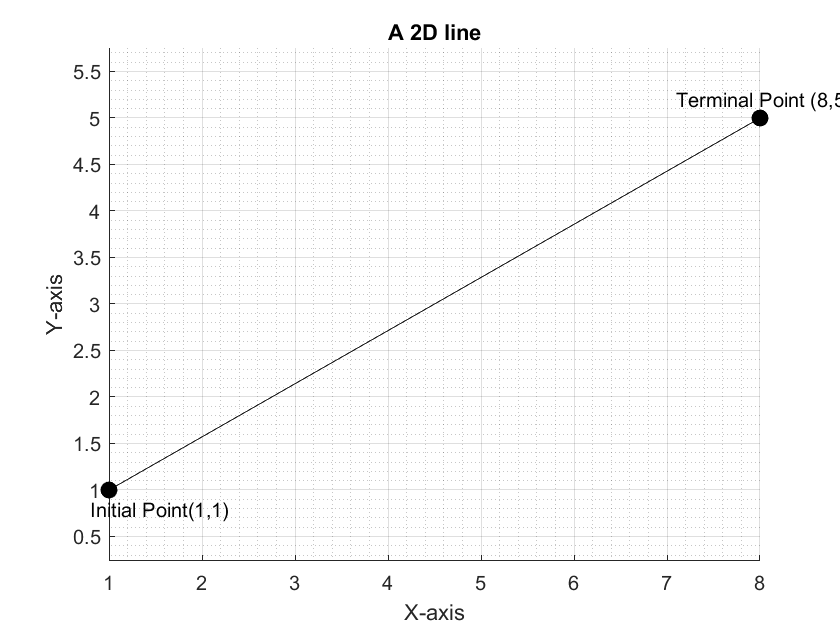

% row vector Q
Q = [8 5];
X = [1 8];
Y = [1 5];
figure
hold on
plot(X,Y,'k-')
plot(1,1,'ko','MarkerSize',8, 'MarkerFaceColor','black')
plot(8,5,'ko', 'MarkerSize', 8, 'MarkerFaceColor','black')
xlabel("X-axis"); ylabel("Y-axis"); 
grid on; grid minor;
title("A 2D line")
text(0.8,0.8,'Initial Point(1,1)',"FontSize",10);
text(7.1,5.2,'Terminal Point (8,5)',"FontSize",10);
axis equal
hold off;

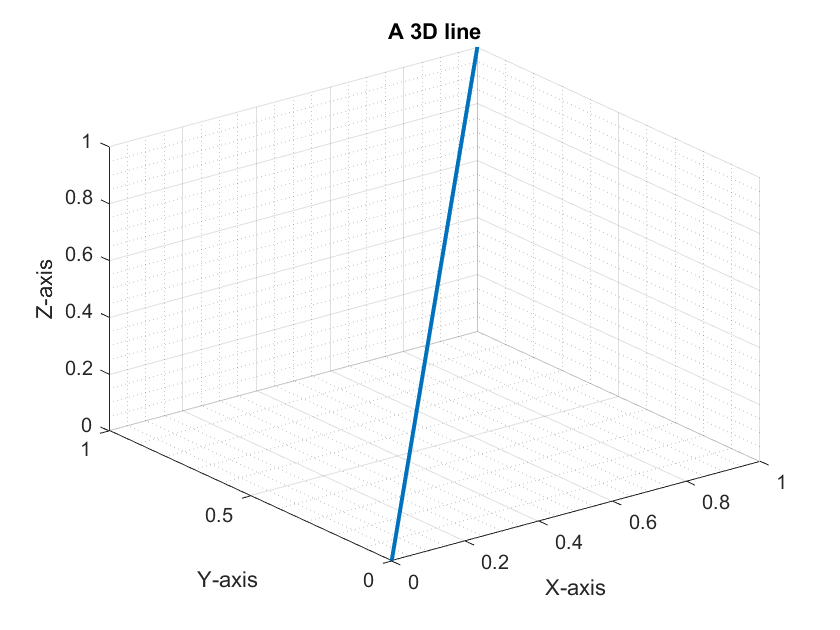


figure;
a = [0, 1];
b = [0, 1];
c = [0, 1];
plot3(a,b,c,'LineWidth',2);
title("A 3D line");
grid on; grid minor;
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");

**3D vectors, magnitude and direction**

**Use the mag() function to compute the magnitude of a 3d vector. Use direction to compute **$\alpha ,\beta ,\textrm{and}\;\gamma \;$**values of the 3D vector**

A = [-1; sym(-2/3); 0]

$$A = \left(\begin{array}{c} -1\\ -\frac{2}{3}\\ 0 \end{array}\right)$$


$$Vector \ \overrightarrow{A} = $$
 
$$\left(\overset{-1}{\underset{0}{-\frac{2}{3}}} \right)$$
  

% mag_A = mag(A)
% Norm function to calculate the magnitude of a vector
mag_A1 = norm(A)

$$mag\_A1 = \frac{\sqrt{13}}{3}$$

Calculate the direction cosine

% [alpha, beta, gamma] = direction(A, mag_A1)
% help direction

Find the coordinates of the centre and radius of the sphere given the equation


$$x^2+y^2+z^2-2x+4y-8z=15$$


After completing the squares, we get

$(x-1)^2+(z-4)^2+(y+2)^2=36$, hence the center, C (1, -2, 4), radius, r = 6

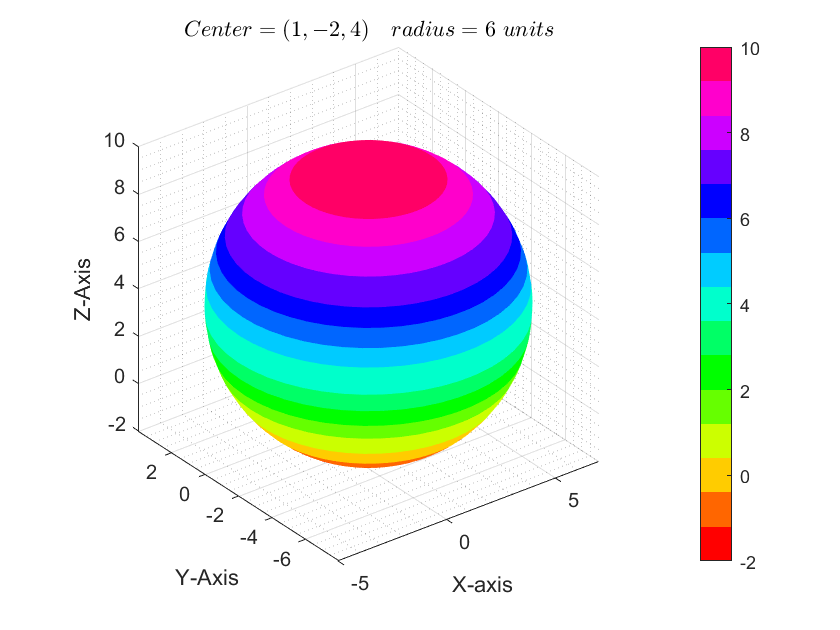

figure;
% argument spheres the number of faces as 50-by-50 faces
[X,Y,Z] = sphere(50);

radius = 6;
% Multiply the respective x,y,z coordinates by the radius(since radius = 1) 
X2 = X * radius;
Y2 = Y * radius;
Z2 = Z * radius;

% To include the x,y,z coordinates, to define the center of the 
% sphere add or subtract them respectively.
% tiledlayout(1,2)
% ax1 = nexttile;
surf(X2+1,Y2-2 ,Z2+4)
shading flat;
colormap(hsv(15))
colorbar
title('$Center = (1, -2, 4) \quad radius = 6 \ units$','Interpreter',"latex")
xlabel('X-axis'); ylabel('Y-Axis'); zlabel('Z-Axis');
grid on; grid minor;
axis equal

A 2D points

x_cor1 = sym([2;3])

$$x\_cor1 = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$

y_cor1 = sym([-1;2])

$$y\_cor1 = \left(\begin{array}{c} -1\\ 2 \end{array}\right)$$

z_cor1 = sym([4;1])

$$z\_cor1 = \left(\begin{array}{c} 4\\ 1 \end{array}\right)$$

3D points

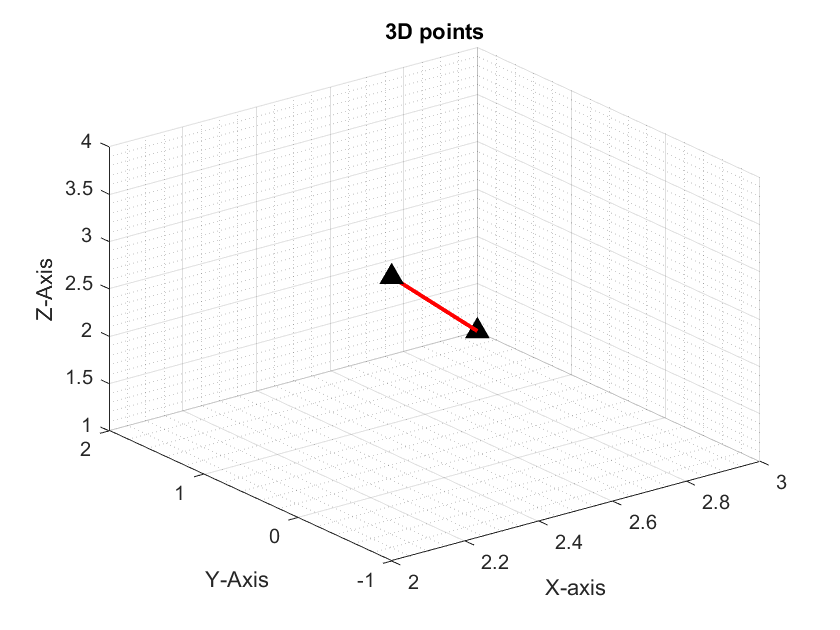

figure
plot3(3,2,1,'k^','MarkerSize',10,'MarkerFaceColor','black')
hold on;
plot3(x_cor1,y_cor1,z_cor1, '-r', "LineWidth",2)
plot3(2,-1,4,'k^','MarkerSize',10,'MarkerFaceColor','black')
title("3D points")
xlabel("X-axis"); ylabel("Y-Axis"); zlabel("Z-Axis")
grid on; grid minor;
hold off;

A = sym([-1; -2; 3])

$$A = \left(\begin{array}{c} -1\\ -2\\ 3 \end{array}\right)$$

B = sym([2; 5; 3])

$$B = \left(\begin{array}{c} 2\\ 5\\ 3 \end{array}\right)$$

Addition of A and B

C = A + B

$$C = \left(\begin{array}{c} 1\\ 3\\ 6 \end{array}\right)$$

Subtraction of A and B

D = A - B

$$D = \left(\begin{array}{c} -3\\ -7\\ 0 \end{array}\right)$$

Dot Product of A and B

E = dot(A,B)

$$E = -3$$

F = cross(A,B)

$$F = \left(\begin{array}{c} -21\\ 9\\ -1 \end{array}\right)$$

Transpose of a matrix

G = A'

$$G = \left(\begin{array}{ccc} -1 & -2 & 3 \end{array}\right)$$

## Finding the distance between a 3D line and a point

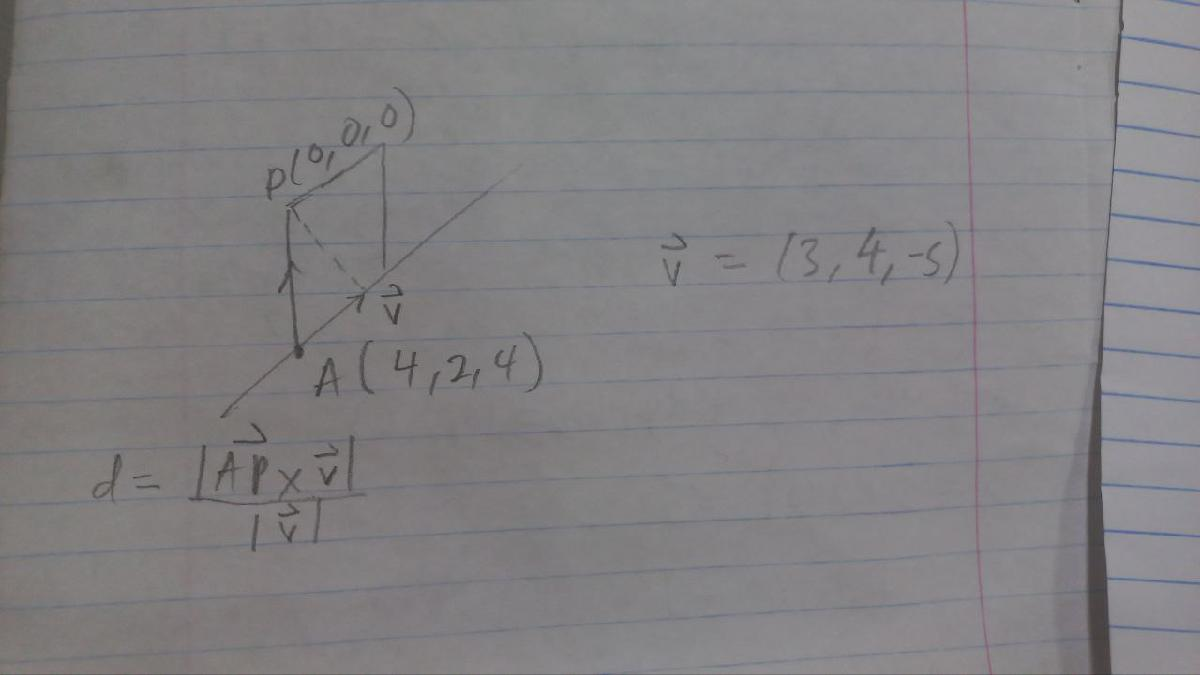

A = [4 2 4]; % A point on the line
P = [0 0 0];
v = [3 4 -5]; % the unit vector of the line

A_P = P - A;
num = norm(cross(A_P,v)) % magnitude of the cross product

num = 42.4264

dem = norm(v) % magnitude of the direction vector

dem = 7.0711

distance = num/dem % distance between the line and the point

distance = 6

## Plot a 3D plane given its equation

z = @(x,y) 2*x + 1.5*y - 4.5 

z = function_handle with value:
    @(x,y)2*x+1.5*y-4.5


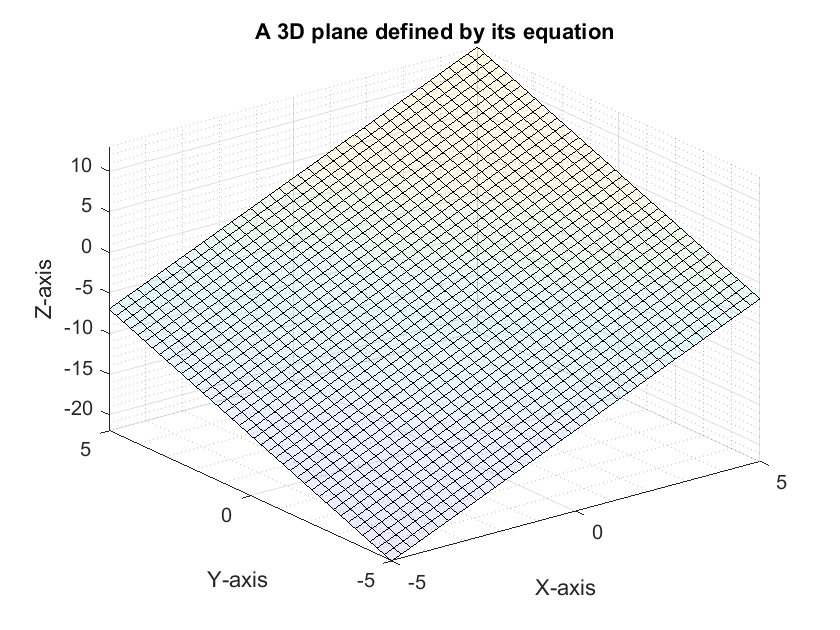

figure1 = figure;
% figure2 = figure;
axes1 = axes(figure1);
plane1 = fsurf(axes1,z);
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A 3D plane defined by its equation");
plane1.MeshDensity = 40;
plane1.FaceAlpha = 0.1; % Define opacity
grid on; grid minor;

## Plot a 3D line given its parametric equations

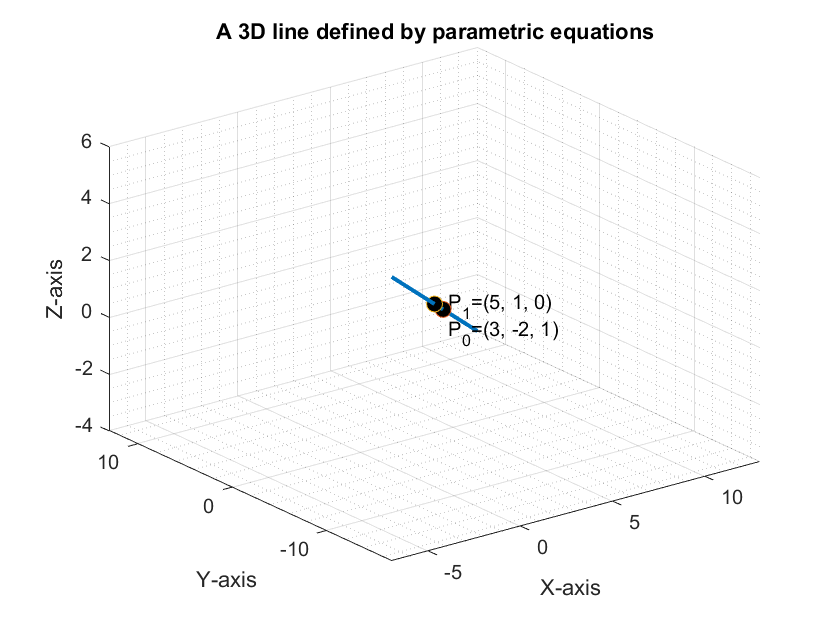

figure2 = figure;
axes2 = axes(figure2);
x = @(t) 3 + 2*t;
y = @(t) -2 + 3*t;
z = @(t) 1 - t;
fig = fplot3(axes2, x, y, z);
fig.LineWidth = 2;
hold on;
plot3(5,1,0,'o','MarkerSize',8,'MarkerFaceColor','k')
text(5.5,1.5,0,'P_1=(5, 1, 0)')
plot3(3,-2,1,'o','MarkerSize',8,'MarkerFaceColor','k')
text(3.5,-2.5,0,'P_0=(3, -2, 1)')
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A 3D line defined by parametric equations");
grid on; grid minor;

## Arc lengths

Find the arc length of the circular helix defined by$r(t) = cos(t) \hat{i} + sin(t)\hat{j} +t \hat{k}$ .(1,0,0) to the point (1,0,$2\pi$) .


$$s(t) = \int_a^b |r'(t)|dt$$
 

syms t
% computing the arc length
r(t) = [2*sin(t) 2*cos(t) -5]

$$r(t) = \left(\begin{array}{ccc} 2\,\sin\left(t\right) & 2\,\cos\left(t\right) & -5 \end{array}\right)$$

deriv = diff(r(t),t)

$$deriv = \left(\begin{array}{ccc} 2\,\cos\left(t\right) & -2\,\sin\left(t\right) & 0 \end{array}\right)$$

squared_deriv = deriv.^2

$$squared\_deriv = \left(\begin{array}{ccc} 4\,{\cos\left(t\right)}^{2} & 4\,{\sin\left(t\right)}^{2} & 0 \end{array}\right)$$

summation = sum(squared_deriv)

$$summation = 4\,{\cos\left(t\right)}^{2}+4\,{\sin\left(t\right)}^{2}$$

squared = sqrt(summation)

$$squared = 2\,\sqrt{{\cos\left(t\right)}^{2}+{\sin\left(t\right)}^{2}}$$

arc_len = int(squared,t,0,2*pi)

$$arc\_len = 4\,\pi$$

integral = vpa(arc_len,5) % This is the arc length from t = 0 to t = 2*pi

$$integral = 12.566$$

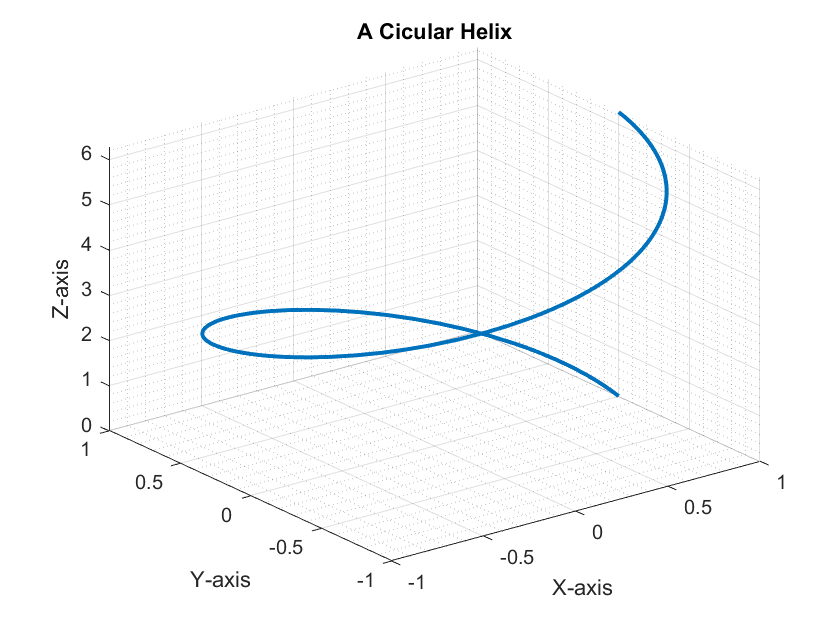


% The circular helix
figure;
xt = @(t) cos(t);
yt = @(t) sin(t);
zt = @(t) t;
fig2 = fplot3(xt,yt,zt,[0 2*pi]);
grid minor; grid on;
fig2.LineWidth = 2;
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A Cicular Helix");

hold off;


## Plot of a multivariable function

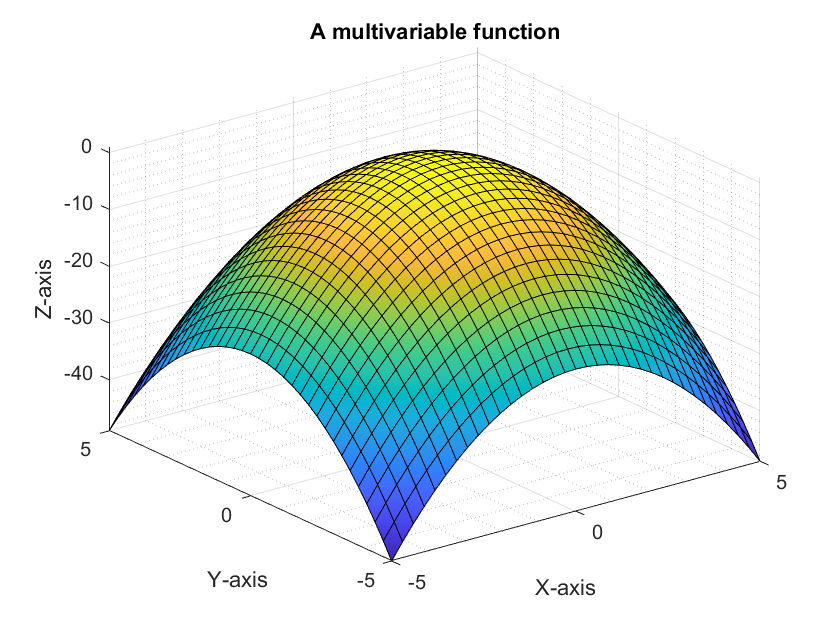

g = @(t,w) 1 - t.^2 - w.^2;
figure3 = figure;
axes3 = axes(figure3);
plane1 = fsurf(axes3,g);
xlabel("X-axis"); ylabel("Y-axis"); zlabel("Z-axis");
title("A multivariable function");
% plane1.MeshDensity = 40;
% plane1.FaceAlpha = 0.5; % Define opacity
grid on; grid minor;

## Compute double integrals


$$$\int_1^2\int_2^4 x^2e^{xy} \ dxdy$$$
 

fun = @(x,y) x.^2.*exp(x.*y)

fun = function_handle with value:
    @(x,y)x.^2.*exp(x.*y)


doubly_integrated = integral2(fun, 2, 4, 1, 2)

doubly_integrated = 5.0193e+03


syms x y z
int(acos(x), x, 0, 0.5)

$$ans = \frac{\pi }{6}-\frac{\sqrt{3}}{2}+1$$

int(exp(x*y),x)

$$ans = \frac{{\mathrm{e}}^{x\,y}}{y}$$

diff(exp(x*y),x)

$$ans = y\,{\mathrm{e}}^{x\,y}$$



g = 3*x^2 + y^2

$$g = 3\,x^{2}+y^{2}$$

inside = int(g, x, y^2-3, y+3)

$$inside = -\left(y+2\right)\,\left(y-3\right)\,\left(y^{4}+y^{3}-y^{2}+3\,y+9\right)$$

outside = int(inside,y, -2, 3)

$$outside = \frac{2375}{7}$$

outside = vpa(outside)

$$outside = 339.28571428571428571428571428571$$



h = x^2 * exp(x*y)

$$h = x^{2}\,{\mathrm{e}}^{x\,y}$$

inside1 = int(h,x,2,4)

$$inside1 = \frac{{\mathrm{e}}^{4\,y}\,\left(16\,y^{2}-8\,y+2\right)}{y^{3}}-\frac{{\mathrm{e}}^{2\,y}\,\left(4\,y^{2}-4\,y+2\right)}{y^{3}}$$

outside1 = int(inside1, y, 1, 2)

$$outside1 = \frac{{\mathrm{e}}^{2}\,\left(7\,{\mathrm{e}}^{6}-15\,{\mathrm{e}}^{2}+4\right)}{4}$$

outside1 = vpa(outside1)

$$outside1 = 5019.3224707976642344856031219924$$


inner = int(h,y,1,2)

$$inner = x\,{\mathrm{e}}^{x}\,\left({\mathrm{e}}^{x}-1\right)$$

outer = int(inner,x,2,4)

$$outer = \frac{{\mathrm{e}}^{2}\,\left(7\,{\mathrm{e}}^{6}-15\,{\mathrm{e}}^{2}+4\right)}{4}$$

outer = vpa(outer)

$$outer = 5019.3224707976642344856031219924$$

first = int(x*exp(2*x),x,2,4)

$$first = \frac{{\mathrm{e}}^{4}\,\left(7\,{\mathrm{e}}^{4}-3\right)}{4}$$

second = int(x*exp(x),x,2,4)

$$second = 3\,{\mathrm{e}}^{4}-{\mathrm{e}}^{2}$$

final = simplify(first - second)

$$final = \frac{{\mathrm{e}}^{2}\,\left(7\,{\mathrm{e}}^{6}-15\,{\mathrm{e}}^{2}+4\right)}{4}$$


syms x
gh = x^2*exp(x*y)

$$gh = x^{2}\,{\mathrm{e}}^{x\,y}$$

% hy = int(gh, y, 0.5*x, 1)
ty = int(gh, y, 0.5*x, 1)

$$ty = -x\,\left({\mathrm{e}}^{\frac{x^{2}}{2}}-{\mathrm{e}}^{x}\right)$$

by = int(x*exp(x), x, 0, 2)

$$by = {\mathrm{e}}^{2}+1$$

## Compute Triple Integrals

function1 = @(x,y,z) x.^2.*y.*z

function1 = function_handle with value:
    @(x,y,z)x.^2.*y.*z


triple_integrated = integral3(function1, -2, 1, 0, 3, 1, 5)

triple_integrated = 162

## Infinite series

syms n
sum = symsum(n/(n+1),n,1,inf)

$$sum = \infty$$

lim = limit(sum,n,inf)

$$lim = \infty$$


sum2 = (n^2+9*n+8)/(n^2+10*n)

$$sum2 = \frac{n^{2}+9\,n+8}{n^{2}+10\,n}$$

lim2 = limit(sum2,n,inf)

$$lim2 = 1$$


sum3 = (n^2+1)/(n+1000)

$$sum3 = \frac{n^{2}+1}{n+1000}$$

lim3 = limit(sum3, n, inf)

$$lim3 = \infty$$


sum4 = (-1)^n

$$sum4 = {\left(-1\right)}^{n}$$

lim4 = limit(sum4,n, inf)

$$lim4 = \mathrm{NaN}$$

## Equation of a plane give three points in the plane

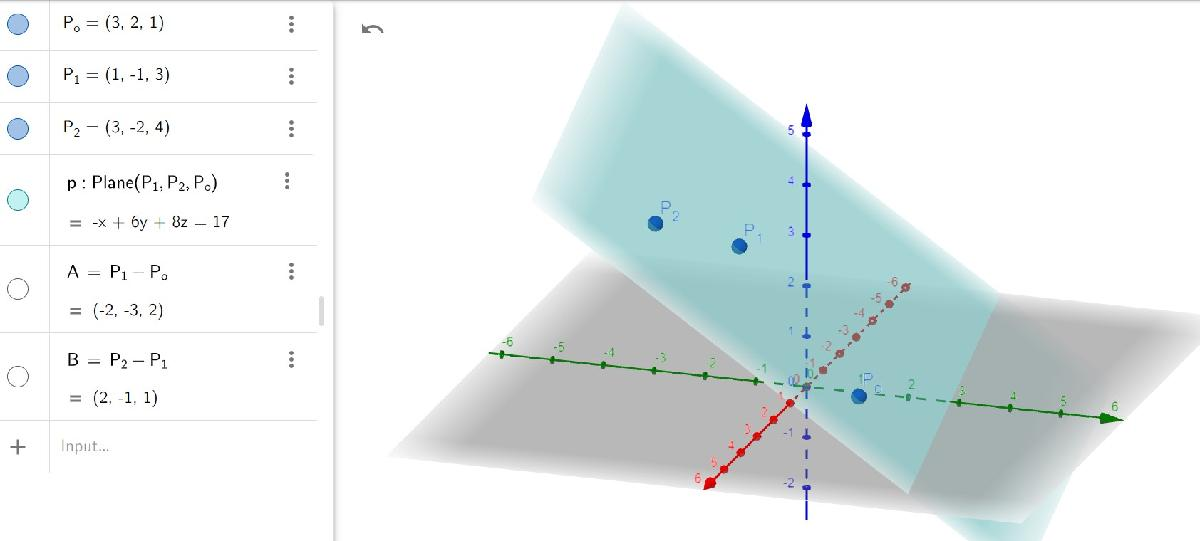

p0 = sym([3 2 1])
p1 = sym([1 -1 3])
p2 = sym([3 -2 4])
p = sym([x y z])
p0p1 = p1 - p0
p0p = p - p0
p0p2 = p2 - p1
triple_product = [p0p1;p0p;p0p2]
result = det(triple_product) == 0;
result

p0 =      1
     1
     4


$$p1 = \left(\begin{array}{ccc} x-1 & y-2 & z+3 \end{array}\right)$$

p2 =     -1
    -4
     2


$$vector = \left(\begin{array}{ccc} 1 & 1 & 4\\ x-1 & y-2 & z+3\\ -1 & -4 & 2 \end{array}\right)$$

$$vector = 6\,y-18\,x+3\,z+15=0$$

$$vector = 2\,y-6\,x+z+5=0$$